% Set the Azure Blob Storage information
storageAccountName = 'historicalpower';
storageContainerName = 'data';
blobName = 'data.xlsx';


SASToken = "sp=r&st=2023-10-28T15:09:02Z&se=2023-10-28T23:09:02Z&spr=https&sv=2022-11-02&sr=b&sig=tsJAx%2FLQcr9GcvouTGexZIovStHCMbIno8ELenD1fq0%3D";
setenv("MW_WASB_SAS_TOKEN",SASToken);


URL = "wasbs://data@historicalpower.blob.core.windows.net/data.xlsx";


data=datastore(URL)

data =   SpreadsheetDatastore with properties:

                      Files: {
                             'wasbs://data@historicalpower.blob.core.windows.net/data.xlsx'
                             }
                    Folders: {
                             'wasbs://data@historicalpower.blob.core.windows.net'
                             }
   AlternateFileSystemRoots: {}
                     Sheets: ''
                      Range: ''

  Sheet Format Properties:
             NumHeaderLines: 0
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'x_2005_07_0100_00_00_0__', 'x13981'}
              VariableTypes: {'char', 'double'}

  Properties that control the table returned by preview, <a href="matlab: help('matlab.io.datastore.SpreadsheetDatastore\read')">read<


Data=read(data)

Data = 8759x2 table
     x_2005_07_0100_00_00_0__      x13981
    ___________________________    ______

    {''2005-07-01 00:00:00.0''}    13162 
    {''2005-07-01 00:00:00.0''}    12699 
    {''2005-07-01 00:00:00.0''}    12464 
    {''2005-07-01 00:00:00.0''}    12599 
    {''2005-07-01 00:00:00.0''}    13242 
    {''2005-07-01 00:00:00.0''}    14740 
    {''2005-07-01 00:00:00.0''}    16502 
    {''2005-07-01 00:00:00.0''}    17689 
    {''2005-07-01 00:00:00.0''}    18548 
    {''2005-07-01 00:00:00.0''}    19188 
    {''2005-07-01 00:00:00.0''}    19599 
    {''2005-07-01 00:00:00.0''}    19763 
    {''2005-07-01 00:00:00.0''}    19972 
    {''2005-07-01 00:00:00.0''}    20037 
    {''2005-07-01 00:00:00.0''}    20018 
    {''2005-07-01 00:00:00.0''}    19937 


% Assuming your data is stored in a variable named 'Data'

% Step 1: Preprocess the data
time = Data(:, 1); % Extract time column
power_consumption = Data(:, 2); % Extract power consumption column



% Perform the normalization once the data type is numeric
normalized_power = (power_consumption - mean(power_consumption))

normalized_power = 8759x1 table
    x13981 
    _______

    -2222.8
    -2685.8
    -2920.8
    -2785.8
    -2142.8
    -644.85
     1117.2
     2304.2
     3163.2
     3803.2
     4214.2
     4378.2
     4587.2
     4652.2
     4633.2
     4552.2



normalized_power=(normalized_power)./ max(normalized_power)

normalized_power = 8759x1 table
     x13981  
    _________

     -0.19329
     -0.23355
     -0.25398
     -0.24224
     -0.18633
    -0.056073
     0.097142
      0.20036
      0.27505
       0.3307
      0.36644
       0.3807
      0.39888
      0.40453
      0.40288
      0.39583


% Convert normalized_power table to an array
normalized_power_array = table2array(normalized_power)

normalized_power_array =    -0.1933
   -0.2335
   -0.2540
   -0.2422
   -0.1863
   -0.0561
    0.0971
    0.2004
    0.2751
    0.3307



% Define the time step for creating sequences
time_step = 24;

% Generate sequences from the normalized data
data_train = [];
for i = 1:size(normalized_power_array, 1) - time_step
    data_train = [data_train; normalized_power_array(i:i+time_step-1)'];
end


data_train

data_train =    -0.1933   -0.2335   -0.2540   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303
   -0.2335   -0.2540   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303   -0.2004
   -0.2540   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303   -0.2004   -0.2538
   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303   -0.2004   -0.2538   -0.2785
   -0.1863   -0.0561   

%data_train=table2array(data_train)
XTrain = data_train(1:end, :) % Use all but the last 24 sequences for training

XTrain =    -0.1933   -0.2335   -0.2540   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303
   -0.2335   -0.2540   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303   -0.2004
   -0.2540   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303   -0.2004   -0.2538
   -0.2422   -0.1863   -0.0561    0.0971    0.2004    0.2751    0.3307    0.3664    0.3807    0.3989    0.4045    0.4029    0.3958    0.3809    0.3452    0.3008    0.2829    0.2388    0.1195   -0.0283   -0.1303   -0.2004   -0.2538   -0.2785
   -0.1863   -0.0561    0.0

YTrain = normalized_power_array(time_step+1:end) % The target for each training sequence is the next value in the time series

YTrain =    -0.2004
   -0.2538
   -0.2785
   -0.2889
   -0.2889
   -0.2382
   -0.1210
    0.0070
    0.0981
    0.1510


# Model training

layers = [ ...
    sequenceInputLayer(time_step) % Define the input layer
    lstmLayer(150) % Define the LSTM layer
    fullyConnectedLayer(1) % Define the fully connected layer
    regressionLayer]; % Define the regression layer

options = trainingOptions('adam', 'MaxEpochs', 200);
net = trainNetwork(XTrain', YTrain', layers, options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         0.39 |      7.6e-02 |          0.0010 |
|      50 |          50 |       00:00:22 |         0.07 |      2.5e-03 |          0.0010 |
|     100 |         100 |       00:00:46 |         0.06 |      1.6e-03 |          0.0010 |
|     150 |         150 |       00:01:09 |         0.05 |      1.2e-03 |          0.0010 |
|     200 |         200 |       00:01:32 |         0.05 |      1.0e-03 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


% Save the trained network
save('trained_net.mat', 'net');

% Clear the current workspace
clear net;

% Load the saved network back into the workspace
loaded_net = load('trained_net.mat');
net = loaded_net.net;

XForecast = data_train(end-time_step+1:end, :); % Use the last 24 sequences for forecasting
YPred = predict(net, XForecast')

YPred = 1x24 single row vector
   -0.0398   -0.1086   -0.1772   -0.2221   -0.2292   -0.1925   -0.1162   -0.0083    0.1139    0.2259    0.3133    0.3699    0.3967    0.4031    0.4007    0.3939    0.3872    0.3838    0.3769    0.3473    0.2798    0.1755    0.0533   -0.0687


# forcasting on normalized power data


% Visualize the results for the last 24 values
last_index = size(normalized_power_array, 1)

last_index = 8759

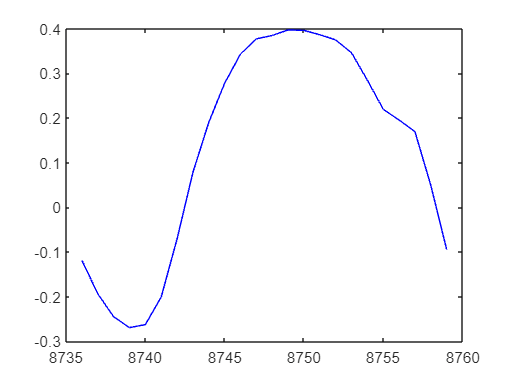


figure;
plot(last_index-23:last_index, normalized_power_array(last_index-23:last_index), 'b'); % Plot the last 24 values of the normalized data
hold on

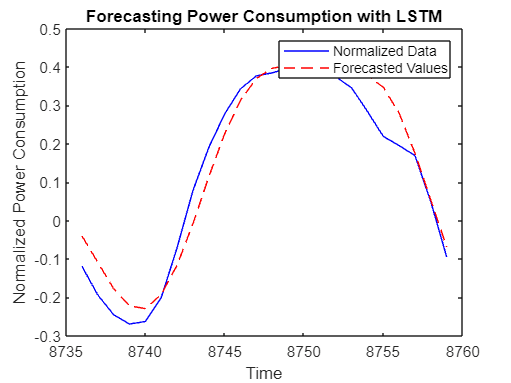


% Plot the forecasted values
time_forecast = last_index-23:last_index; % Assuming YPred is a 1x24 vector
plot(time_forecast,  YPred, 'r--'); % Plot the forecasted values

% Add labels and title
legend('Normalized Data', 'Forecasted Values');
xlabel('Time');
ylabel('Normalized Power Consumption');
title('Forecasting Power Consumption with LSTM');

# forcasting on original data

figure;
power_consumption_array = table2array(power_consumption);
max_power = max(power_consumption_array);
mean_power = mean(power_consumption_array);

YPred_original_scale = YPred * max_power + mean_power

YPred_original_scale = 1x24 single row vector
1.0e+04 *

    1.4315    1.2465    1.0621    0.9413    0.9222    1.0209    1.2261    1.5160    1.8447    2.1458    2.3808    2.5329    2.6049    2.6221    2.6157    2.5975    2.5796    2.5704    2.5519    2.4722    2.2906    2.0104    1.6818    1.3538


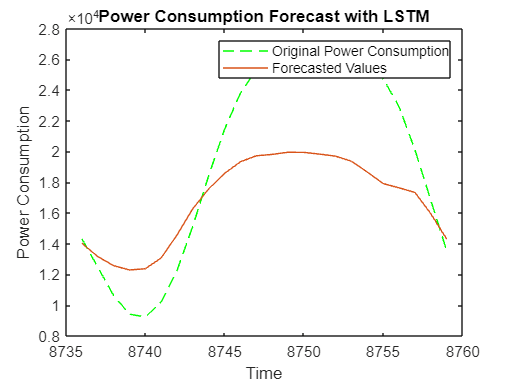


% Plot the forecasted values in the original power consumption scale
time_forecast = last_index-23:last_index; % Assuming YPred is a 1x24 vector
plot(time_forecast, YPred_original_scale, 'g--'); % Plot the forecasted values

hold on
plot(time_forecast,power_consumption_array(last_index-23:last_index))

% Add labels and title
legend('Original Power Consumption', 'Forecasted Values');
xlabel('Time');
ylabel('Power Consumption');
title('Power Consumption Forecast with LSTM');

# forcasting on unknown 24 hours data



% Assuming net is the trained LSTM model
num_forecast_hours = 24;  % Number of hours to forecast

% Use the last 'time_step' hours as initial input for forecasting
XForecast = normalized_power_array(end-time_step+1:end)';

% Initialize an array to store forecasted values
YPredo = zeros(1, num_forecast_hours);

% Forecast the next 24 hours
for i = 1:num_forecast_hours
    % Predict the next value
    YPredo(i) = predict(net, XForecast');
    
    % Update XForecast with the new value for the next iteration
    XForecast = [XForecast(2:end), YPredo(i)];
end


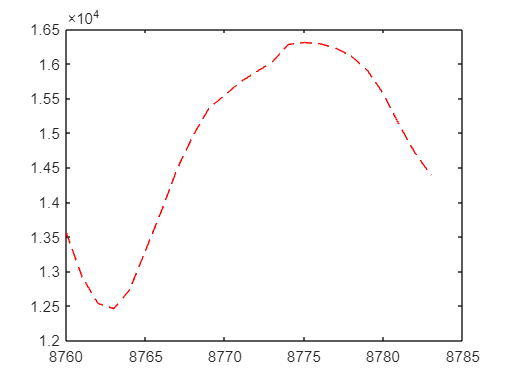


figure;
power_consumption_array = table2array(power_consumption);
max_power = max(power_consumption_array);
mean_power = mean(power_consumption_array);
YPred_original_scale = YPredo * max_power + mean_power;

% Plot the forecasted values in the original power consumption scale
time_forecast = last_index+1:last_index+num_forecast_hours; % Assuming YPred is a 1x24 vector
plot(time_forecast, YPred_original_scale, 'r--'); % Plot the forecasted values

% Read the true values from the Excel file
true_values_table = readtable('/MATLAB Drive/BTP/valdata.xlsx');
true_values = table2array(true_values_table(:,2))

true_values =        12930
       12045
       11457
       11133
       10999
       10953
       11557
       12839
       14386
       15633


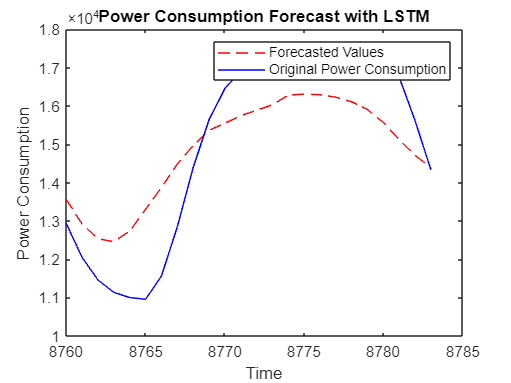



hold on;
plot(time_forecast, true_values, 'b'); % Plot the true values
legend('Original Power Consumption', 'True Values');

% Add labels and title
legend('Forecasted Values','Original Power Consumption');
xlabel('Time');
ylabel('Power Consumption');
title('Power Consumption Forecast with LSTM');

# forcasting on 1year next

% Assuming net is the trained LSTM model
num_forecast_days = 365;  % Number of days to forecast

% Use the last 'time_step' hours as initial input for forecasting
XForecast = normalized_power_array(end-time_step+1:end)';

% Initialize an array to store forecasted values
YPred = zeros(1, num_forecast_days*24);  % Assuming 24 data points per day

% Forecast for one year
for i = 1:num_forecast_days*24
    % Predict the next value
    YPred(i) = predict(net, XForecast');
    
    % Update XForecast with the new value for the next iteration
    XForecast = [XForecast(2:end), YPred(i)];
end

power_consumption_array = table2array(power_consumption);

% Denormalize the forecasted values
max_power = max(power_consumption_array);
mean_power = mean(power_consumption_array);
YPred_original_scale = YPred * max_power + mean_power

% Plot the forecasted values in the original power consumption scale
time_forecast = last_index+1:last_index+num_forecast_days*24;
figure;
plot(time_forecast, YPred_original_scale, 'b-', 'LineWidth', 2); % Plot the forecasted values with a solid blue line

% Add labels and title
xlabel('Time (hours)');
ylabel('Power Consumption');
title('Power Consumption Forecast for One Year with LSTM');
grid on; % Add grid lines

% Define the number of days and data points per day
num_days = 365;
data_points_per_day = 24;

% Calculate the average of every 24 points
YPred_daily_average = mean(reshape(YPred_original_scale, data_points_per_day, num_days), 1);

% Plot the averaged values for each day
figure;
plot(1:num_days, YPred_daily_average, 'b-', 'LineWidth', 1.5);
title('Daily Average Power Consumption Forecast for One Year');
xlabel('Day');
ylabel('Average Power Consumption');
grid on;

# using rnn created layer

layers = [
    sequenceInputLayer(time_step) % Define the input layer
    fullyConnectedLayer(200) % Define the fully connected layer with 150 hidden units
    tanhLayer % Apply the tanh activation function
    fullyConnectedLayer(1) % Define the fully connected layer
    regressionLayer]; % Define the regression layer

options = trainingOptions('adam', 'MaxEpochs', 200);
net = trainNetwork(XTrain', YTrain', layers, options);

XForecast = data_train(end-time_step+1:end, :); % Use the last 24 sequences for forecasting
YPred = predict(net, XForecast')


% Visualize the results for the last 24 values
last_index = size(normalized_power_array, 1)

figure;
plot(last_index-23:last_index, normalized_power_array(last_index-23:last_index), 'b'); % Plot the last 24 values of the normalized data
hold on


% Plot the forecasted values
time_forecast = last_index-23:last_index; % Assuming YPred is a 1x24 vector
plot(time_forecast,  YPred, 'r--'); % Plot the forecasted values

% Add labels and title
legend('Normalized Data', 'Forecasted Values');
xlabel('Time');
ylabel('Normalized Power Consumption');
title('Forecasting Power Consumption with LSTM');


% Assuming net is the trained LSTM model
num_forecast_hours = 24;  % Number of hours to forecast

% Use the last 'time_step' hours as initial input for forecasting
XForecast = normalized_power_array(end-time_step+1:end)';

% Initialize an array to store forecasted values
YPredo = zeros(1, num_forecast_hours);

% Forecast the next 24 hours
for i = 1:num_forecast_hours
    % Predict the next value
    YPredo(i) = predict(net, XForecast');
    
    % Update XForecast with the new value for the next iteration
    XForecast = [XForecast(2:end), YPredo(i)];
end



figure;
power_consumption_array = table2array(power_consumption);
max_power = max(power_consumption_array);
mean_power = mean(power_consumption_array);
YPred_original_scale = YPredo * max_power + mean_power;

% Plot the forecasted values in the original power consumption scale
time_forecast = last_index+1:last_index+num_forecast_hours; % Assuming YPred is a 1x24 vector
plot(time_forecast, YPred_original_scale, 'r--'); % Plot the forecasted values




% Read the true values from the Excel file
true_values_table = readtable('/MATLAB Drive/BTP/valdata.xlsx');
true_values = table2array(true_values_table(:,2))


hold on;
plot(time_forecast, true_values, 'b'); % Plot the true values
legend('Original Power Consumption', 'True Values');

% Add labels and title
legend('Forecasted Values','Original Power Consumption');
xlabel('Time');
ylabel('Power Consumption');
title('Power Consumption Forecast with LSTM');
